clear;
clc;
numcardsh = 2;
numcardsv = 5;
pxCards = numcardsh*numcardsv;
px = pxCards*48;

width = 60;
hexsize = width / sqrt(3)

hexsize = 34.6410

## Matlab Colormap

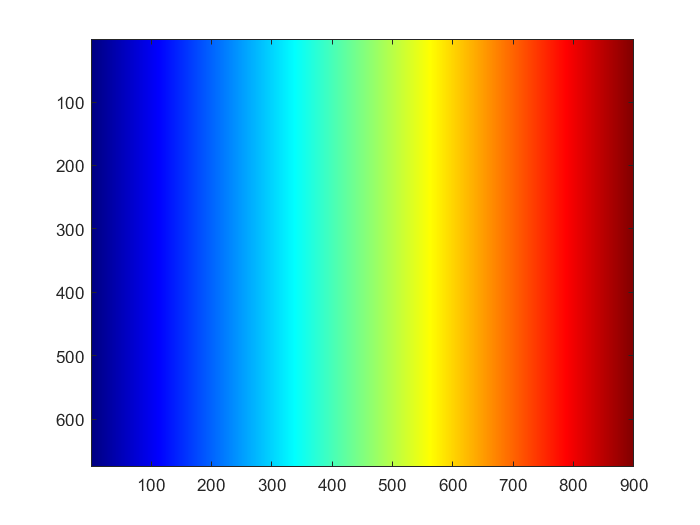

% RGBWjet = reshape(ones(10,1)*reshape(jet(12),1,36),[10,12,3]);
% imagesc(RGBWjet(:,:,1:3))
% addpath('hex');
rows = 10;
cols = 12;
addpath('../hex');
[n,m] = getMappingMatrixSize(cols,rows,hexsize);
RGBWjet = reshape(ones(m,1)*reshape(jet(n),1,n*3),[m,n,3]);
imagesc(RGBWjet(:,:,1:3))

RGBWjet(:,:,4) = zeros(m,n);
qrMatrix = mapMatrix(cols,rows,RGBWjet,hexsize);


% 
% size = size
% rows = 10;
% cols = 12;
% [n,m] = getMappingMatrixSize(cols,rows,size);
% 
% RGBWjet = reshape(ones(m,1)*reshape(jet(n),1,n*3),[m,n,3]);
% imagesc(RGBWjet(:,:,1:3))
% 
% %RGBWjet = imresize(RGBWjet,[n m]);
% B = getEvenrMappingMatrix(m,n,size);
% 
% imagesc(RGBWjet)
% RGBWjet(:,:,4) = zeros(m,n);
% %RGBWjet = RGBWjet.*128;
% 
% qrMatrix = zeros(rows,cols);
% 
% for col = 1:cols
%     for row = 1:rows
%         [rety retx] = find(B(:,:,1) == col & B(:,:,2) == row);
%         
%         rgbw = zeros(numel(retx),4);
%         
%         for i = 1:numel(retx)
%             rgbw(i,:) = RGBWjet(rety(i),retx(i),:) ;
%         end
%         
%         qrMatrix(row,col,1:4) = mean(rgbw);
% 
%                 
%     end
% end



## moon.jpg

I = imread('moon.jpg');
I = imresize(I,[m n]);
I(:,:,4) = zeros(m,n);
qrMatrix = mapMatrix(cols,rows,I,hexsize);

%imagesc(I(:,:,1:3))
%imagesc(uint8(qrMatrix(:,:,1:3)))


qrMatrix = flipdim(qrMatrix,1);


## NYANCAT!!!!



[gifImage, cmap] = imread('nyancat.gif', 'Frames', 'all');
[rows, columns, numColorChannels, numImages] = size(gifImage);
% Construct an RGB movie.
rgbImage = zeros(rows, columns, 3, numImages, 'uint8'); % Initialize dimensions.
hFig = figure;
for k = 1 : numImages
  thisFrame = gifImage(:,:,:, k);
  thisRGB = uint8(255 * ind2rgb(thisFrame, cmap));
%   imshow(thisRGB);
  rgbImage(:,:,:,k) = thisRGB;
%   caption = sprintf('Frame %#d of %d', k, numImages);
%   title(caption);
  drawnow;
end
close(hFig);
% Show the constructed movie.
% uiwait(msgbox('Click OK to bring up the GIF in implay'));
% implay(rgbImage);

nyan{numImages} = [];

for i= 1:numImages
    
    I = imresize(I,[m n]);
    I(:,:,4) = zeros(m,n);
    
    nyan{i} = imresize(rgbImage(:,:,:,i),[m n]);
    nyan{i}(:,:,4) = zeros(m,n);
    nyan{i} = int16(mapMatrix(12,10,nyan{i},hexsize));
    nyan{i} = flip(flip(nyan{i}),2);
end

for i = 1:numImages
    fb = matrixToFramebuffer(nyan{i},px);

    if i == 1
        fileID = fopen('img.bin','w');
        fwrite(fileID,fb);
        fclose(fileID);
    else
        fileID = fopen('img.bin','a');
        fwrite(fileID,fb);
        fclose(fileID);
    end
end

## write file, send over ssh

%     fb = matrixToFramebuffer(qrMatrix,px);
%     fileID = fopen('img.bin','w');
%     fwrite(fileID,fb);
%     fclose(fileID);
    
ssh = false;

if ssh
    ssh2_conn = ssh2_config('beagleled.local','debian','asdw132');
    ssh2_conn = scp_put(ssh2_conn, 'img.bin','~',pwd,'img.bin');
    ssh2_conn = ssh2_close(ssh2_conn);
end

'ssh2_config' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\phili\Dropbox\uni\bscthesis\Matlab\image\ssh2_v2_m1_r7

Change the MATLAB current folder or add its folder to the MATLAB path.



% fileID = fopen('img.bin','w');
% fwrite(fileID,fb);
% fclose(fileID);
% ssh2_conn = ssh2_config('beagleled.local','debian','asdw132');
% ssh2_conn = scp_put(ssh2_conn, 'img.bin','/dev/',pwd,'fbuf');
% ssh2_conn = ssh2_close(ssh2_conn);



function fb = matrixToFramebuffer(RGBW,px)
fb = uint8(zeros(px*3/2,1));
% convert RGBW Matrix to Framebuffer
for j = 0:9
    for i = 0:11 %m
        r = uint16(RGBW(j+1,i+1,1));
        g = uint16(RGBW(j+1,i+1,2));
        b = uint16(RGBW(j+1,i+1,3));
        w = uint16(RGBW(j+1,i+1,4));
        
        % 6 bits of fb
        %             self.fb[3*i] = ((br_cur >> 4) & 0xff)
        %             self.fb[3*i+1] = ((br_cur & 0x0f) << 4) + ((br_next >> 8) & 0x0f)
        %             self.fb[3*i+2] = (br_next & 0xff)
        fb(6*(j*12+i)+1) = bitand(bitsrl(w,4), 255);
        fb(6*(j*12+i)+2) = bitsll(bitand(w,15),4) + bitand(bitsrl(b,8),15);
        fb(6*(j*12+i)+3) = bitand(b,255);
        fb(6*(j*12+i)+4) = bitand(bitsrl(g,4), 255);
        fb(6*(j*12+i)+5) = bitsll(bitand(g,15),4) + bitand(bitsrl(r,8),15);
        fb(6*(j*12+i)+6) = bitand(r,255);
    end
end
fb = sortFramebuffer(fb,px);
end

function fbc = sortFramebuffer(fb,px)
% sort the fb

fbc = uint8(zeros(px*3/2,1));
% pxLen = 6;
pxFrame = 1:6;
for i = 0:4
    fbc(i*144+6*0+pxFrame) = fb(i*144+6*0+pxFrame);
    fbc(i*144+6*1+pxFrame) = fb(i*144+6*12+pxFrame);
    fbc(i*144+6*2+pxFrame) = fb(i*144+6*13+pxFrame);
    fbc(i*144+6*3+pxFrame) = fb(i*144+6*1+pxFrame);
    
    fbc(i*144+6*4+pxFrame) = fb(i*144+6*2+pxFrame);
    fbc(i*144+6*5+pxFrame) = fb(i*144+6*14+pxFrame);
    fbc(i*144+6*6+pxFrame) = fb(i*144+6*15+pxFrame);
    fbc(i*144+6*7+pxFrame) = fb(i*144+6*3+pxFrame);
    
    fbc(i*144+6*8+pxFrame) = fb(i*144+6*4+pxFrame);
    fbc(i*144+6*9+pxFrame) = fb(i*144+6*16+pxFrame);
    fbc(i*144+6*10+pxFrame) = fb(i*144+6*17+pxFrame);
    fbc(i*144+6*11+pxFrame) = fb(i*144+6*5+pxFrame);
    
    fbc(i*144+6*12+pxFrame) = fb(i*144+6*6+pxFrame);
    fbc(i*144+6*13+pxFrame) = fb(i*144+6*18+pxFrame);
    fbc(i*144+6*14+pxFrame) = fb(i*144+6*19+pxFrame);
    fbc(i*144+6*15+pxFrame) = fb(i*144+6*7+pxFrame);
    
    fbc(i*144+6*16+pxFrame) = fb(i*144+6*8+pxFrame);
    fbc(i*144+6*17+pxFrame) = fb(i*144+6*20+pxFrame);
    fbc(i*144+6*18+pxFrame) = fb(i*144+6*21+pxFrame);
    fbc(i*144+6*19+pxFrame) = fb(i*144+6*9+pxFrame);
    
    fbc(i*144+6*20+pxFrame) = fb(i*144+6*10+pxFrame);
    fbc(i*144+6*21+pxFrame) = fb(i*144+6*22+pxFrame);
    fbc(i*144+6*22+pxFrame) = fb(i*144+6*23+pxFrame);
    fbc(i*144+6*23+pxFrame) = fb(i*144+6*11+pxFrame);
end

end